% cut and align the neural activity based on task event written by NY

clear all;
close all;
clc;


Animal = 'Rbp4c878';%'tph314'; %'tph199';'tph209'
Date = '20240715'; %'20240414'; % '20230602';'20230827'
totalTrial = 150;
Key = 'switching'; %'roving'; %'heavy90';'roving25s'
cellset_num = 5; %3; %5; % num of session in all sessions % start from 0
categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
layer_bounds_um = [191, 249, 303, 380, 412, 434]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
%     Inscopix imaging FOV % tph199:[247; 433; 358] 
Kota_alignment = 0; %0: do not use, 1:use
% Define the folder where the CSV files are located
pullAlignFolderPath = '/home/naohiro/Documents/Inscopix_Projects/tph314_roving/20240414_tph314/output';
% need to be fixed because reverse pattern is different between tph189 and tph199 
image_reverse = 3; %2; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1
% gamma = 0.9; % discount factor
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022/';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
data_folder = ['/media/naohiro/Volume/Nao_behavior/202407'  filesep Date '_' Animal '_' Key]; % from 24/7
% data_folder = ['/media/naohiro/SSD-SCTU3A/Nao_behavior/202403'  filesep Date '_' Animal '_' Key]; % from 24/6
% data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation/202308'  filesep Date '_' Animal '_' Key]; % Linux %/202308
% load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
% behavior_data = behavior_neural_time_convolved_zscored;
output_parent_dir = ['/home/naohiro/Desktop/Doya_rotation/analysis/output/241002/'];

% plot event triggered neural activity
force_thr = 50; 
position_thr = 10;
fps = 10;
before_event = 2; %1;
after_event  = 4; %2;
norm = 3; %0:no normalization or 1:normalization or 2:z scored or 3:z scored and take only significantly changed cell 
% 4:z scored by compared trials 5: z scored and align with trian data (half) and plot with test data (half) 6: z scored by before pull neural
% activity
rng(1);
load([data_folder filesep Animal '_behavior_' Date '_' Key '.mat']);
load([data_folder filesep Animal '_neural_activity_' Date '_' Key '.mat']);

% Outputパスのフォルダ名を生成
folder_name = [Date '_' Animal '_norm' num2str(norm) 'neural_act'];

% 新しいフォルダのパスを作成
output_dir = fullfile(output_parent_dir, folder_name);

% フォルダが存在しない場合は作成
if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

% パスの最後に'/'を追加
if ~endsWith(output_dir, '/')
    output_dir = [output_dir '/'];
end

% フォルダ作成およびパスを表示
disp(['フォルダが作成されました: ' output_dir]);

% ファイル名を生成
filename = [output_dir Date '_' Animal '_norm' num2str(norm) '_parameter.json'];

% パラメータを構造体としてまとめる
params.Animal = Animal;
params.Date = Date;
params.totalTrial = totalTrial;
params.Key = Key;
params.cellset_num = cellset_num;
params.categorize = categorize;
params.layer_bounds_um = layer_bounds_um;
params.Kota_alignment = Kota_alignment;
params.pullAlignFolderPath = pullAlignFolderPath;
params.image_reverse = image_reverse;
params.working_directory = working_directory;
params.output_dir = output_dir;
params.data_folder = data_folder;
params.force_thr = force_thr;
params.position_thr = position_thr;
params.fps = fps;
params.before_event = before_event;
params.after_event = after_event;
params.norm = norm;

% JSONファイルとして保存
jsonText = jsonencode(params);
fid = fopen(filename, 'w');
if fid == -1
    error('ファイルを開くことができませんでした。');
end
fwrite(fid, jsonText, 'char');
fclose(fid);

disp(['パラメータが保存されました: ' filename]);

% Multivariate Granger Causality Analysis Implementation for Neurons with Layer Separation

% 1. Generate sample data
% Parameters for sample data generation
num_time_points = 60; % Number of time points
num_trials = 40;       % Number of trials
num_neurons = 20;     % Number of neurons
sampling_rate = 10;   % Sampling rate in Hz (assuming 100 Hz)
movement_onset_time = 20; % Time point index for movement onset

% Generate synthetic Df/f data
% Simulate neural activity with some temporal structure
time = (0:num_time_points-1) / sampling_rate; % Time vector
data = zeros(num_time_points, num_trials, num_neurons);

for neuron = 1:num_neurons
    for trial = 1:num_trials
        % Simulate baseline activity
        baseline = 0.1 * randn(1, num_time_points);
        % Simulate event-related activity starting at movement onset
        event_activity = zeros(1, num_time_points);
        event_activity(movement_onset_time:end) = ...
            0.5 * exp(-0.1 * (time(1:end-movement_onset_time+1)));
        % Combine baseline and event activity
        data(:, trial, neuron) = baseline + event_activity + 0.05 * randn(1, num_time_points);
    end
end

% 2. Layer information
% Assign layers to neurons (e.g., half in Layer 23 and half in Layer 5)
num_layer23 = round(num_neurons / 2);
layer_info = zeros(num_neurons, 1);
layer_info(1:num_layer23) = 23;
layer_info(num_layer23+1:end) = 5;

% 3. Normalize Df/f data based on activity 2 seconds before movement onset
% Define the indices for the 2 seconds before movement onset
pre_movement_duration = 2; % seconds
pre_movement_points = pre_movement_duration * sampling_rate;
pre_movement_indices = (movement_onset_time - pre_movement_points + 1):(movement_onset_time - 1);

% Ensure indices are within valid range
pre_movement_indices = pre_movement_indices(pre_movement_indices >= 1);

for trial = 1:num_trials
    for neuron = 1:num_neurons
        % Calculate the mean activity during the 2 seconds before movement onset
        baseline_activity = mean(data(pre_movement_indices, trial, neuron));
        % Subtract the baseline activity from the entire time series
        data(:, trial, neuron) = data(:, trial, neuron) - baseline_activity;
    end
end

% 4. Rearrange data to [nvars x nobs x ntrials]
data_rearranged = permute(data, [3, 1, 2]); % Now data is [neurons x time_points x trials]

% Parameters for Granger causality analysis
num_lags_max = 20; % Reduced maximum number of lags
alpha = 0.01;     % Significance level for conditional Granger causality
regmode = 'OLS';  % Regression mode ('OLS' or 'LWR')

% 5. Estimate model order (AIC)
model_order = estimate_model_order(data_rearranged, num_lags_max, regmode);

model order = 1
model order = 2
model order = 3
model order = 4
model order = 5
model order = 6
model order = 7
model order = 8
model order = 9
model order = 10
model order = 11
model order = 12
model order = 13
model order = 14
model order = 15
model order = 16
model order = 17
model order = 18
model order = 19
model order = 20


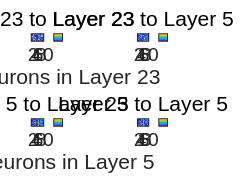


function model_order = estimate_model_order(data, num_lags_max, regmode)
    % data: [nvars x nobs x ntrials]
    % num_lags_max: Maximum number of lags to consider
    % regmode: Regression mode ('OLS' or 'LWR')
    % Calculate information criteria (AIC, BIC) for model orders from pmin to num_lags_max
    pmin = 1; % Minimum model order
    [AIC, BIC] = tsdata_to_infocrit(data, num_lags_max, regmode); %tsdata_to_infocrit(data, pmin, num_lags_max, 'OLS');
    % Select the model order with minimum AIC
    [~, model_order_idx] = min(AIC);
    model_order = model_order_idx + pmin - 1; % Adjust for pmin
end

% 6. Calculate time-domain Granger causality using the selected model order
F = mvgc_analysis(data_rearranged, model_order, alpha, regmode);

function F = mvgc_analysis(data, model_order, alpha, regmode)
    % data: [nvars x nobs x ntrials]
    % model_order: Model order (number of lags)
    % alpha: Significance level
    % regmode: Regression mode ('OLS' or 'LWR')
    % Fit VAR model
    [A, SIG] = tsdata_to_var(data, model_order, regmode);
    assert(~isbad(A), 'VAR estimation failed');
    
    % Calculate autocovariance sequence
    [G, info] = var_to_autocov(A, SIG);
    assert(~info.error, 'VAR to autocovariance failed');
    
    % Calculate pairwise conditional Granger causality
    F = autocov_to_pwcgc(G);
    % assert(~isbad(F), 'Granger causality calculation failed');

    % Significance testing
    nvars = size(data, 1); % Total number of variables (neurons)
    nobs = size(data, 2);  % Number of observations (time points)
    ntrials = size(data, 3); % Number of trials
    N = nobs * ntrials;    % Total number of observations
    nx = 1; % Number of variables in X (from-variable)
    ny = 1; % Number of variables in Y (to-variable)
    nz = nvars - nx - ny; % Number of conditioning variables
    m = nvars * model_order; % Degrees of freedom for the full model
    tstat = 'F'; % Test statistic type

    % Compute p-values
    pval = zeros(nvars, nvars);
    for i = 1:nvars
        for j = 1:nvars
            if i ~= j
                F_ij = F(i, j);
                pval(i, j) = mvgc_pval(F_ij, model_order, m, N, nx, ny, nz, tstat);
            end
        end
    end

    % Apply significance mask
    sig = pval < alpha;
    F(~sig) = 0;
end

% 7. Rearrange F matrix for visualization
% Get the indices of neurons, with L23 neurons first, then L5 neurons

% 7. Separate Granger causality matrices for Layer 23 and Layer 5
layer23_indices = find(layer_info == 23);
layer5_indices = find(layer_info == 5);

% Extract submatrices for visualization
F_layer23 = F(layer23_indices, layer23_indices);
F_layer5 = F(layer5_indices, layer5_indices);
F_layer23_to_layer5 = F(layer5_indices, layer23_indices);
F_layer5_to_layer23 = F(layer23_indices, layer5_indices);
sorted_indices = [layer23_indices; layer5_indices];

% Rearrange F matrix
F_sorted = F(sorted_indices, sorted_indices);

% 8. Visualization

% Previous individual subplots (optional)
figure;
subplot(2,2,1);
imagesc(F_layer23);
title('Layer 23 to Layer 23');
colorbar;
xlabel('From Neurons in Layer 23');
ylabel('To Neurons in Layer 23');

subplot(2,2,2);
imagesc(F_layer23_to_layer5);
title('Layer 23 to Layer 5');
colorbar;
xlabel('From Neurons in Layer 23');
ylabel('To Neurons in Layer 5');

subplot(2,2,3);
imagesc(F_layer5_to_layer23);
title('Layer 5 to Layer 23');
colorbar;
xlabel('From Neurons in Layer 5');
ylabel('To Neurons in Layer 23');

subplot(2,2,4);
imagesc(F_layer5);
title('Layer 5 to Layer 5');
colorbar;
xlabel('From Neurons in Layer 5');
ylabel('To Neurons in Layer 5');

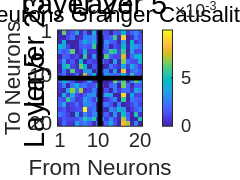


% New: All cells heatmap with L23 and L5 separated
figure;
imagesc(F_sorted);
title('All Neurons Granger Causality');
colorbar;
xlabel('From Neurons');
ylabel('To Neurons');

% Add lines to separate layers
num_L23 = length(layer23_indices);
num_L5 = length(layer5_indices);
hold on;
% Horizontal line to separate layers
plot([0.5, num_neurons+0.5], [num_L23+0.5, num_L23+0.5], 'k-', 'LineWidth', 2);
% Vertical line to separate layers
plot([num_L23+0.5, num_L23+0.5], [0.5, num_neurons+0.5], 'k-', 'LineWidth', 2);
hold off;

% Adjust axis ticks and labels
xticks([1, num_L23, num_neurons]);
xticklabels({'1', num2str(num_L23), num2str(num_neurons)});
yticks([1, num_L23, num_neurons]);
yticklabels({'1', num2str(num_L23), num2str(num_neurons)});

% Optionally, add labels or annotations for layers
text(num_L23/2, -5, 'Layer 23', 'HorizontalAlignment', 'center', 'FontSize', 12);
text(num_L23 + num_L5/2, -5, 'Layer 5', 'HorizontalAlignment', 'center', 'FontSize', 12);
text(-5, num_L23/2, 'Layer 23', 'Rotation', 90, 'HorizontalAlignment', 'center', 'FontSize', 12);
text(-5, num_L23 + num_L5/2, 'Layer 5', 'Rotation', 90, 'HorizontalAlignment', 'center', 'FontSize', 12);